# Análise de Séries Temporais Não Estacionárias e Previsão de Quedas Bruscas de Cotações 

## Análise de Estacionaridade

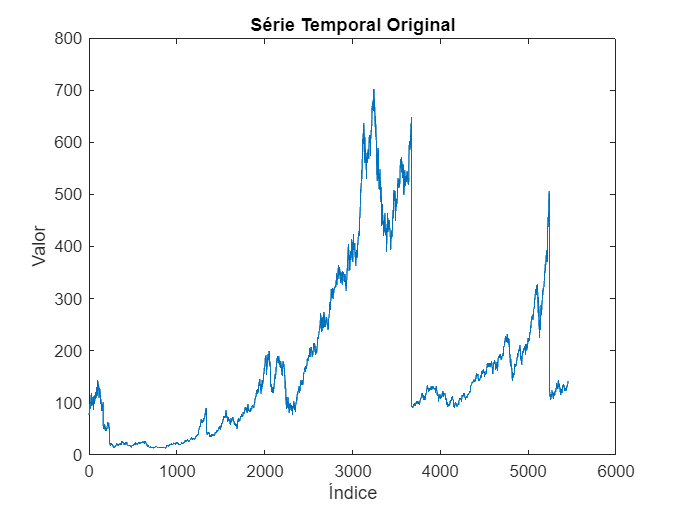

% Carregar a série temporal
data = load('AppleStocks.mat'); 
serie = data.AppleStock;
serie = serie(~isnan(serie));

% Visualizar a série temporal
figure;
plot(serie);
title('Série Temporal Original');
xlabel('Índice');
ylabel('Valor');


% Teste Dickey-Fuller aumentado
fprintf('Teste Dickey-Fuller Aumentado:\n');

Teste Dickey-Fuller Aumentado:


[h_adf, p_adf] = adftest(serie);
if h_adf
    disp('A hipótese nula de não estacionaridade foi rejeitada. A série é estacionária.');
else
    disp('A hipótese nula de não estacionaridade não foi rejeitada. A série não é estacionária.');
end

A hipótese nula de não estacionaridade não foi rejeitada. A série não é estacionária.



% Teste KPSS
fprintf('\nTeste KPSS:\n');


Teste KPSS:


[h_kpss, p_kpss] = kpsstest(serie);
if h_kpss
    disp('A hipótese nula de estacionaridade foi rejeitada. A série não é estacionária.');
else
    disp('A hipótese nula de estacionaridade não foi rejeitada. A série é estacionária.');
end

A hipótese nula de estacionaridade foi rejeitada. A série não é estacionária.


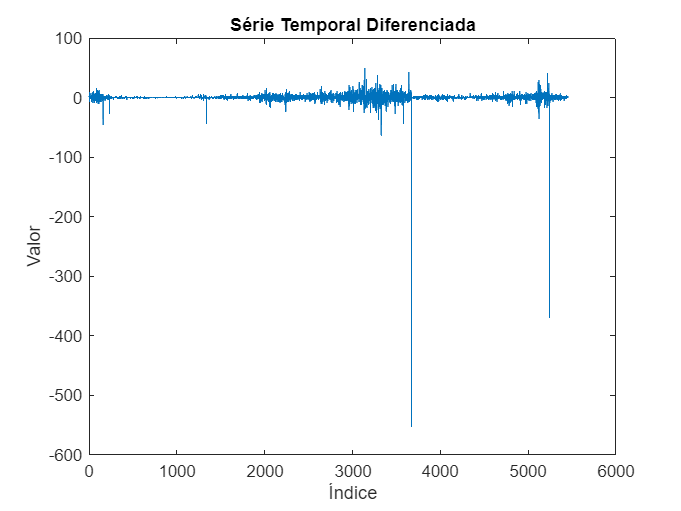


Teste Dickey-Fuller Aumentado após diferenciação:


A hipótese nula de não estacionaridade foi rejeitada. A série diferenciada é estacionária.



Teste KPSS após diferenciação:


A hipótese nula de estacionaridade não foi rejeitada. A série diferenciada é estacionária.



% Diferenciação
if ~h_adf || h_kpss
    serie_dif = diff(serie);
    figure;
    plot(serie_dif);
    title('Série Temporal Diferenciada');
    xlabel('Índice');
    ylabel('Valor');

    % Repetir testes na série diferenciada
    fprintf('\nTeste Dickey-Fuller Aumentado após diferenciação:\n');
    [h_adf_dif, p_adf_dif] = adftest(serie_dif);
    if h_adf_dif
        disp('A hipótese nula de não estacionaridade foi rejeitada. A série diferenciada é estacionária.');
    else
        disp('A hipótese nula de não estacionaridade não foi rejeitada. A série diferenciada não é estacionária.');
    end

    fprintf('\nTeste KPSS após diferenciação:\n');
    [h_kpss_dif, p_kpss_dif] = kpsstest(serie_dif);
    if h_kpss_dif
        disp('A hipótese nula de estacionaridade foi rejeitada. A série diferenciada não é estacionária.');
    else
        disp('A hipótese nula de estacionaridade não foi rejeitada. A série diferenciada é estacionária.');
    end
end

Avaliando os resultados dos testes de estacionaridade, uma diferenciação em primeira ordem é suficiente para tornar a série original estacionária.

## Modelação da Série Temporal

### ARIMA

Primeiramente obtiveram-se as funções de autocorrelação (ACF) e autocorrelação parcial (PACF) para averiguar as ordens do modelo a usar.

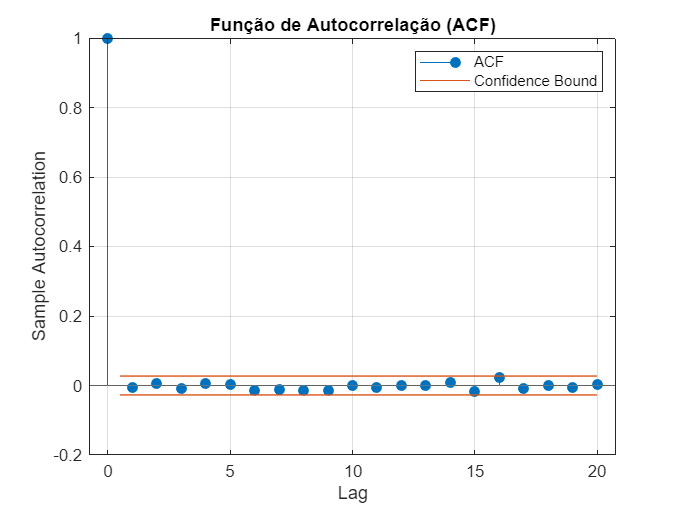

serie_modelar = diff(serie);

% Plot das funções ACF e PACF
figure;
autocorr(serie_modelar);
title('Função de Autocorrelação (ACF)');

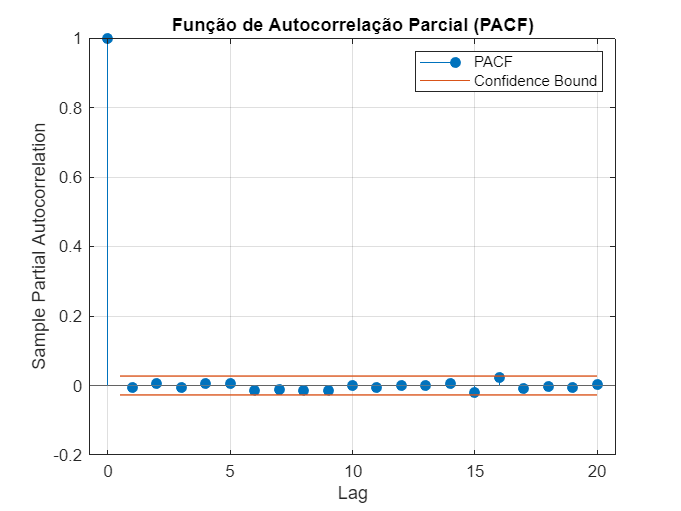

figure;
parcorr(serie_modelar);
title('Função de Autocorrelação Parcial (PACF)');

Pela avaliação das mesmas, é claro que o nosso modelo MA é de ordem 0 e o modelo AR também é ordem 0:

% Construir o modelo
model_arima = arima(0, 1, 0); 
estim_arima = estimate(model_arima, serie);

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic    PValue 
                ________    _____________    __________    _______

    Constant    0.011807       0.28828        0.040955     0.96733
    Variance      101.67        0.1307          777.93           0



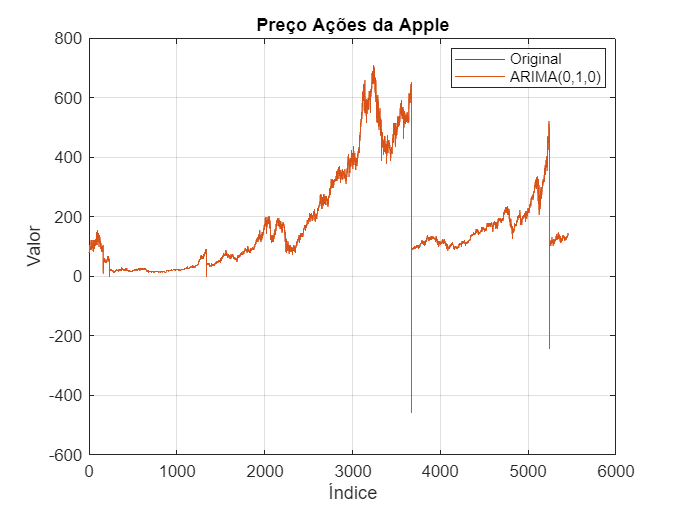


% Previsões do modelo ARIMA
[residuals_arima, variances_arima] = infer(estim_arima, serie);
prediction = serie + residuals_arima;

% Plot
figure
plot(1:length(serie), serie);
hold on
plot(1:length(serie), prediction);
title('Preço Ações da Apple');
ylabel('Valor');
xlabel('Índice');
legend('Original','ARIMA(0,1,0)','Location','best');
grid on
hold off

Teste de ruído branco, heterocedasticidade e histograma dos resíduos:

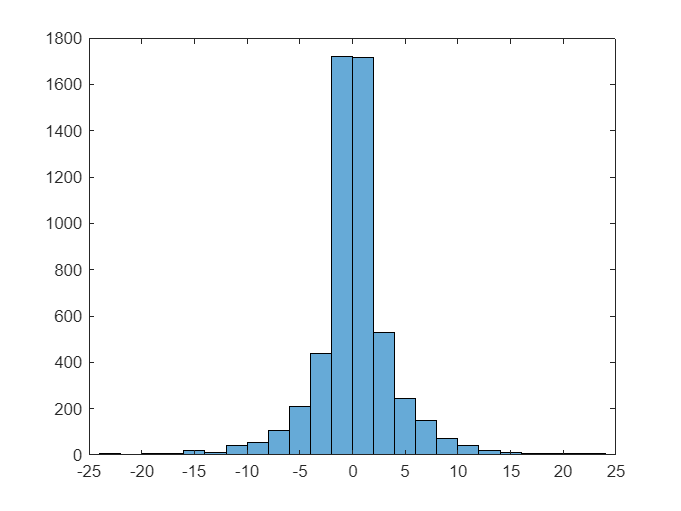

% Histograma dos resíduos
histogram(residuals_arima);
xlim([-25, 25]);


% Teste de ruído branco nos resíduos
[h_lb, ~] = lbqtest(residuals_arima);
if h_lb
    disp('Teste ruído branco: Os resíduos não são ruído branco.');
else
    disp('Teste ruído branco: Os resíduos são ruído branco.');
end

Teste ruído branco: Os resíduos são ruído branco.



% Teste ARCH nos resíduos
[h_arch, ~] = archtest(residuals_arima);
if h_arch == 1
    disp('Teste ARCH: há evidência de heterocedasticidade.');
else
    disp('Teste ARCH: não há evidência de heterocedasticidade significativo.');
end

Teste ARCH: não há evidência de heterocedasticidade significativo.


Com estes testes e os resíduos terem uma distribuição aproximadamente normal, conclui-se que o modelo ajustado é um bom candidato a modelar a série original.

Podemos agora tentar prever o comportamento da série usando os primeiros 80% da série para backtesting e os restantes 20% para previsão.

% Dividir a série 
serie_1 = serie(1:floor(0.8 * length(serie))); % 80% da série original
serie_2 = serie(floor(0.8 * length(serie)) + 1:end); % Os restantes 20%
len = length(serie_2);

% Ajustar modelo ARIMA
model_arima2 = arima(0, 1, 0); 
estim_arima2 = estimate(model_arima2, serie_1);

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic    PValue 
                ________    _____________    __________    _______

    Constant    0.014124       0.30268        0.046663     0.96278
    Variance       90.54       0.11309           800.6           0



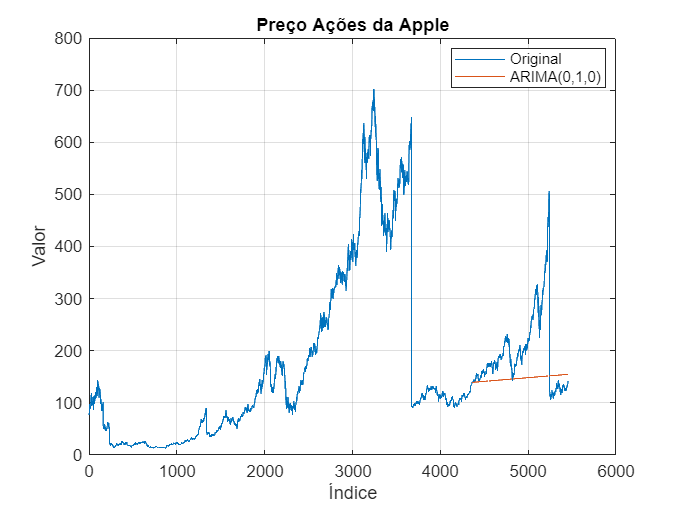


% Previsão
ARIMA_CloseFinalForecast2 = forecast(estim_arima2, len, 'Y0', serie_1);

% Gráfico
figure;
plot(1:length(serie), serie, 'DisplayName', 'Original'); 
hold on;
plot(length(serie_1) + 1:length(serie_1) + len, ARIMA_CloseFinalForecast2, 'DisplayName', 'ARIMA(0,1,0)');
title('Preço Ações da Apple');
ylabel('Valor');
xlabel('Índice');
legend('show', 'Location', 'best');
grid on;
hold off;

Conclusão: o modelo não é adequado para previsão (expectável). 

O modelo ARIMA é um modelo linear, pelo que assume que os valores futuros podem ser previstos com base em combinações lineares de valores e erros passados. Além disto, o modelo arima não considera variações na volatilidade (comportamento comum em séries financeiras), pelo que não consegue capturar a heterocedasticidade do modelo.

### ARIMA + GARCH

A seguir encontra-se uma variação do código anterior onde se incorpora o modelo GARCH para tentar melhorar a previsão:

% Dividir a série
serie_1 = serie(1:floor(0.8 * length(serie))); % 80% da série original
serie_2 = serie(floor(0.8 * length(serie)) + 1:end); % Os restantes 20%
len = length(serie_2);

% ARIMA
model_arima2 = arima(0, 1, 0); 
estim_arima2 = estimate(model_arima2, serie_1);

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic    PValue 
                ________    _____________    __________    _______

    Constant    0.014124       0.30268        0.046663     0.96278
    Variance       90.54       0.11309           800.6           0




% Resíduos ARIMA
[residuals_arima, ~] = infer(estim_arima2, serie_1);

% Ajustar GARCH nos resíduos do ARIMA
model_garch = garch(1, 1); 
estim_garch = estimate(model_garch, residuals_arima);

 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0027176     0.00031896        8.5201      1.5941e-17
    GARCH{1}        0.962     0.00045824        2099.3               0
    ARCH{1}      0.038001     0.00052415          72.5               0



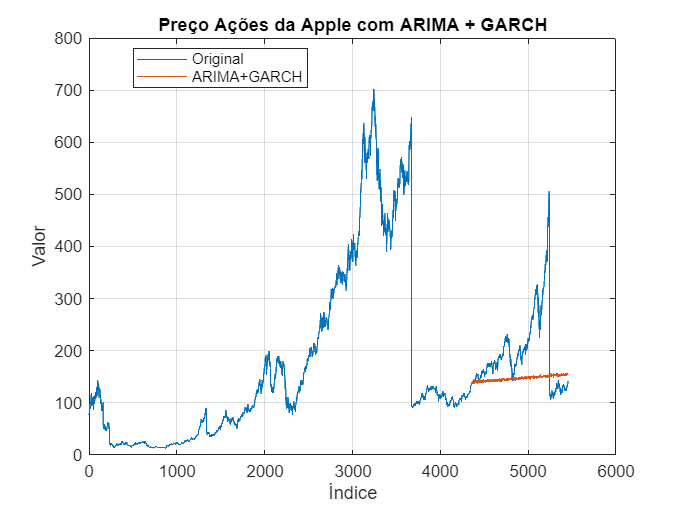


% Variância condicional do GARCH
cond_variances_garch = infer(estim_garch, residuals_arima);

% Prever com ARIMA
ARIMA_CloseFinalForecast2 = forecast(estim_arima2, len, 'Y0', serie_1);

% Ajustar previsões de ARIMA usando a volatilidade condicional
adjusted_forecast = ARIMA_CloseFinalForecast2 + sqrt(cond_variances_garch(end)) * randn(len, 1);

% Plot
figure;
plot(1:length(serie), serie, 'DisplayName', 'Original'); 
hold on;
plot(length(serie_1) + 1:length(serie_1) + len, adjusted_forecast, 'DisplayName', 'ARIMA+GARCH');
title('Preço Ações da Apple com ARIMA + GARCH');
ylabel('Valor');
xlabel('Índice');
legend('show', 'Location', 'best');
grid on;
hold off;

Pode-se observar que mesmo usando GARCH para capturar a heterocedasticidade dos dados, a previsão continua a falhar. Este resultado seria de esperar, pois as bolsas de valores não são facilmente previstas, principalmente quando as mudanças se devem a fatores externos e aleatórios (ruído não capturado pelo modelo).

## Análise de Quedas Bruscas nas Cotações

No código seguinte fez-se um estudo do comportamento da série para uma janela com um tamanho definido arbitrariamente antes de cada queda considerada. Primeiramente detetaram-se as quedas de pelo menos 40% (foi uma decisão arbitrária para o que seria uma queda "brusca") e procedeu-se então ao estudo de três critérios considerados relevantes: Média das Variâncias Condicionais, Média dos resíduos e Volatilidade. 

### Estudo estatístico das características da série modelada antes da queda

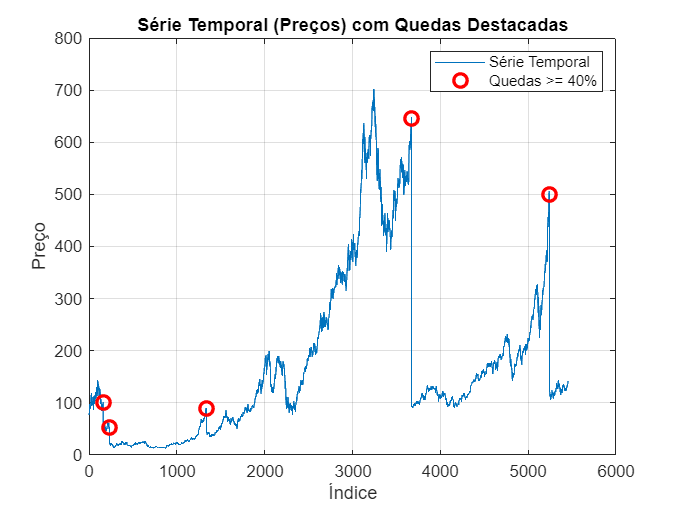

% Identificar quedas bruscas
percentagem_queda = 0.6; % Quedas superiores a 40%
indices_quedas = find(serie(2:end) ./ serie(1:end-1) <= percentagem_queda);

% Série Original
figure('Name','Série Temporal com Quedas (>= 40%) Destacadas');
plot(1:length(serie), serie, '-','DisplayName','Série Temporal');
hold on;
plot(indices_quedas, serie(indices_quedas), 'ro',...
    'MarkerSize', 8, 'LineWidth', 2, 'DisplayName','Quedas >= 40%');
hold off;
title('Série Temporal (Preços) com Quedas Destacadas');
xlabel('Índice');
ylabel('Preço');
legend;
grid on;


% ARIMA(0,1,0)
model_arima = arima(0,1,0); 
estim_arima = estimate(model_arima, serie);

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic    PValue 
                ________    _____________    __________    _______

    Constant    0.011807       0.28828        0.040955     0.96733
    Variance      101.67        0.1307          777.93           0




% Resíduos do ARIMA
[residuals_arima, variances_arima] = infer(estim_arima, serie);

% Ajuste do modelo GARCH(1,1) nos resíduos
model_garch = garch(1,1);
estim_garch = estimate(model_garch, residuals_arima);

 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic     PValue  
                _________    _____________    __________    _________

    Constant    0.0042247     0.00038881        10.866      1.681e-27
    GARCH{1}      0.95367     0.00019673        4847.7              0
    ARCH{1}      0.046327     0.00023382        198.13              0




% Variância condicional do GARCH
cond_variances_garch = infer(estim_garch, residuals_arima);

% Cálculos locais antes da queda
window_size = 10;

% -- Inicializar --
mean_conditional_variance = nan(length(indices_quedas),1);
mean_residuals            = nan(length(indices_quedas),1);
volatility                = nan(length(indices_quedas),1);

for i = 1:length(indices_quedas)
    
    idx_queda = indices_quedas(i); 
    start_idx = idx_queda - window_size;
    end_idx   = idx_queda - 1;
    
    if start_idx < 1
        continue;
    end

    window_indices = start_idx : end_idx;

    % Média das variâncias condicionais (GARCH)
    y_variance = cond_variances_garch(window_indices);
    mean_conditional_variance(i) = mean(y_variance);

    % Média dos resíduos (em valor absoluto)
    y_residual = abs(residuals_arima(window_indices));
    mean_residuals(i) = mean(y_residual);

    % Volatilidade
    volatility(i) = std(residuals_arima(window_indices));
end

% Tabela de Resultados
T = table(indices_quedas, mean_conditional_variance, ...
          mean_residuals, volatility,...
          'VariableNames', {'Indice_Queda','Mean_CondVar',...
                            'Mean_AbsRes','Volatility'});
                        
fprintf('---------------------------------------\n');

---------------------------------------


fprintf('Resultados (métricas antes das quedas):\n');

Resultados (métricas antes das quedas):


disp(T);

    Indice_Queda    Mean_CondVar    Mean_AbsRes    Volatility
    ____________    ____________    ___________    __________

         161           18.472         2.8386         3.3335  
         231           10.498         2.4807         2.9525  
        1337           3.6098         2.0606         2.2274  
        3672           65.689         5.7693         5.8378  
        5241           109.24         6.3556         8.7658  



Avaliando os resultados e comparando-os visualmente com o resto da série, a conclusão final é que os critérios considerados não exibiam qualquer tipo de padrão antes de se dar a queda. 

### Previsão de Quedas

A seguir encontra-se um script que podia ser usado para antecipar quedas, no entanto, é importante salientar que há imensos falsos negativos exatamente porque vários pontos que não antecedem quedas partilham as mesmas propriedades estatísticas que pontos que antecedem quedas.

% Ajustar modelo ARIMA
model_arima = arima(0, 1, 0);
estim_arima = estimate(model_arima, serie);

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic    PValue 
                ________    _____________    __________    _______

    Constant    0.011807       0.28828        0.040955     0.96733
    Variance      101.67        0.1307          777.93           0




% Obter resíduos do ARIMA
[residuals_arima, ~] = infer(estim_arima, serie);

% Ajustar modelo GARCH
model_garch = garch(1, 1);
estim_garch = estimate(model_garch, residuals_arima);

 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic     PValue  
                _________    _____________    __________    _________

    Constant    0.0042247     0.00038881        10.866      1.681e-27
    GARCH{1}      0.95367     0.00019673        4847.7              0
    ARCH{1}      0.046327     0.00023382        198.13              0



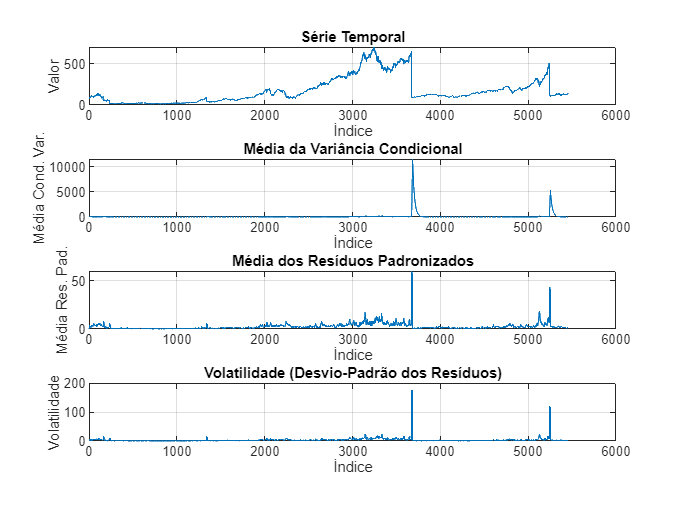


% Obter variâncias condicionais
cond_variances_garch = infer(estim_garch, residuals_arima);

% Inicializar métricas
n = length(residuals_arima);
window_size = 10;
highlight_points = false(n, 1);
mean_conditional_variances = zeros(n, 1);
mean_standardized_residuals = zeros(n, 1);
volatility = zeros(n, 1);

% Thresholds
mean_variance_limit = 65;
mean_residual_limit = 5;
volatility_limit = 5; 

% Cálculos locais para todos os pontos
for i = 1:n
    if i <= window_size
        window_indices = 1:i;
    else
        window_indices = (i - window_size):(i - 1);
    end

    % Calcular métricas locais
    mean_variance = mean(cond_variances_garch(window_indices));
    mean_residual = mean(abs(residuals_arima(window_indices)));

    mean_conditional_variances(i) = mean_variance;
    mean_standardized_residuals(i) = mean_residual;
    volatility(i) = std(residuals_arima(window_indices));

    % Destacar pontos baseados nos limites
    if (mean_variance > mean_variance_limit) && ...
       (mean_residual > mean_residual_limit) && ...
       (volatility(i) > volatility_limit)
        highlight_points(i) = true;
    end
end

% Gráficos das métricas calculadas
figure('Name','Métricas Locais');
subplot(4, 1, 1);
plot(1:length(serie), serie, '-', 'DisplayName', 'Série Temporal');
title('Série Temporal');
xlabel('Índice');
ylabel('Valor');
grid on;

subplot(4, 1, 2);
plot(1:n, mean_conditional_variances, '-', 'DisplayName', 'Média Cond. Variance');
title('Média da Variância Condicional');
xlabel('Índice');
ylabel('Média Cond. Var.');
grid on;

subplot(4, 1, 3);
plot(1:n, mean_standardized_residuals, '-', 'DisplayName', 'Média Resíduos Padronizados');
title('Média dos Resíduos Padronizados');
xlabel('Índice');
ylabel('Média Res. Pad.');
grid on;

subplot(4, 1, 4);
plot(1:n, volatility, '-', 'DisplayName', 'Volatilidade');
title('Volatilidade (Desvio-Padrão dos Resíduos)');
xlabel('Índice');
ylabel('Volatilidade');
grid on;

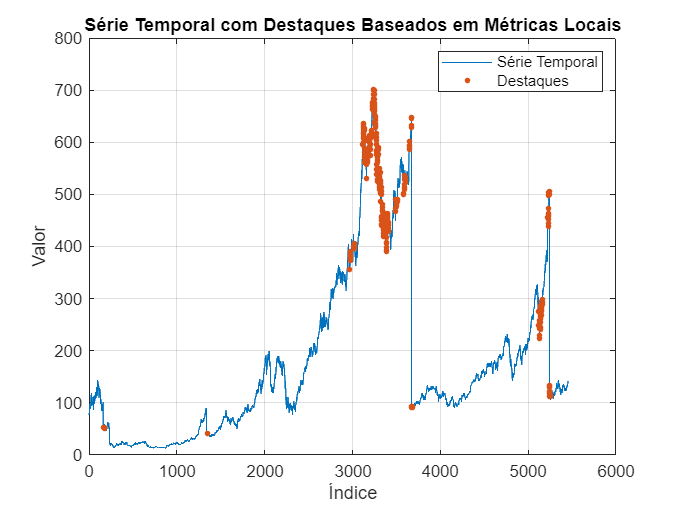


% Gráfico com destaque para todos os pontos
figure('Name','Série Temporal com Destaques');
plot(1:length(serie), serie, '-', 'DisplayName', 'Série Temporal');
hold on;
highlight_indices = find(highlight_points);
plot(highlight_indices, serie(highlight_indices), '.', 'MarkerSize', 10, 'DisplayName', 'Destaques');
hold off;
title('Série Temporal com Destaques Baseados em Métricas Locais');
xlabel('Índice');
ylabel('Valor');
legend('show');
grid on;

Os pontos após a queda evidenciam altas médias porque estiveram sujeitos a variações bruscas recentemente, então aparecem destacados no gráfico, o que contribui ainda mais para o aparecimento de falsos negativos.

De forma geral, verifica-se que é possível antecipar quedas, mas não de forma precisa uma vez que fatores externos têm um papel e peso muito grandes e que não são captados pela série e portanto não são previsíveis.